# 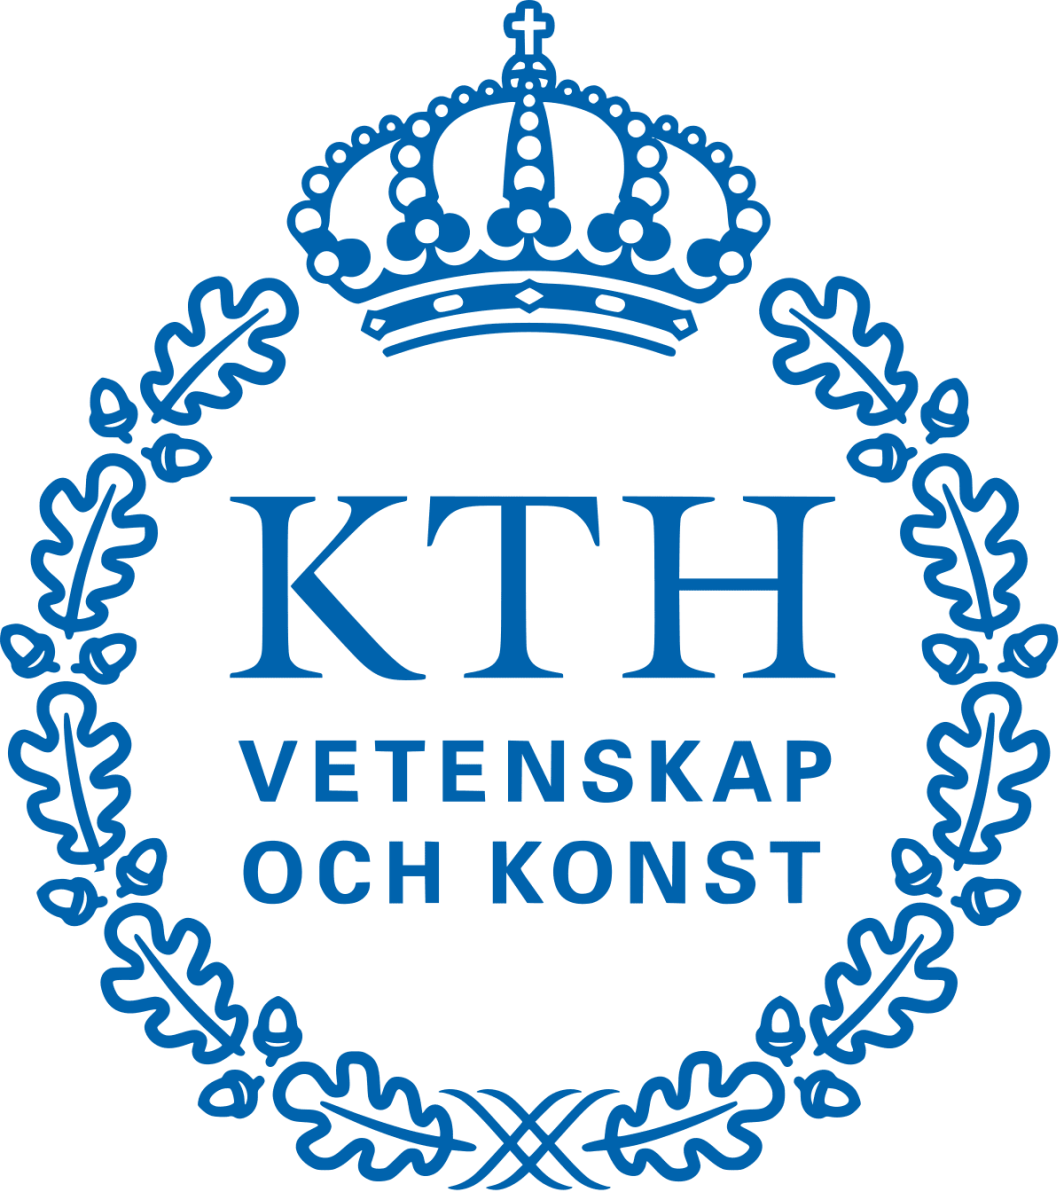

# SD2125 Signals and Mechanical Systems

# HOME ASSIGNMENT 3 (HA3)

# STUDENT 1 Marcus von Post Carlsson

# STUDENT 2 Spencer Huerta Karlström

In this exercise, you will learn about (1) spectral leakage and how to avoid it, (2) how to use the Welch method to calculate power spectral density (PSD) and cross-power spectral density (CPSD). Finally (3), different spectra will be used to analyze different signals. The assignment is intended to be in pairs, but it is also fine to do it alone (in that case, please remove the STUDENT 2 line). 

The product help under the help menu in MATLAB is recommended to use when understanding what predefined functions are suitable to implement. Pay special attention to how MATLAB outputs are organized. It is recommended to "Run Section" instead of "Run" (the whole code) to prevent unnecessary code runs.  

# INSTRUCTIONS FOR ASSIGNMENT AND REPORT

In this Live Script, you will find **empty CODE slots **where you must fill in relevant codes and **empty ANSWER slots **where you must fill in answers to given questions. The structure of the Live Script should not be modified, that is, **do not change/remove headings, numberings, or sections—even if you submit blank in any of them**. Make sure you also add your name(s) at the top of this document (here). If you did the assignment alone, add your name in Student 1 and delete the row for Student 2. 

Once you are finished with your assignment, you should produce a PDF report out of the Live Script. No introduction, discussion nor conclusion are required in the report, only answer the questions and show the plots as instructed. You can produce the PDF report by clicking `"Save As..."` and selecting **PDF (*.pdf)** format. 

**OBS**: **Make sure you save the PDF file including the name(s) of the student(s) who did the work: HA3_Initial-Surname_Initial-Surname, for example: "**`HA3_K-Bolin_E-Zea.pdf`**".  **

# 1. LEAKAGE

## 1.1 Spectral leakage

Start by creating a sinusoidal signal with added random noise. Use the commands: 

% add your code here
f = 10; % Frequency (Hz)
t = [1:64e3]'/1e3; % Time vector
x = sin(2*pi*f*t) + randn(size(t))/10;


### 1.1.1.     Plot signal in time (N = 400)

Plot the first 400 samples of the signal versus time. Be aware that this makes the signal periodic in the time window. 

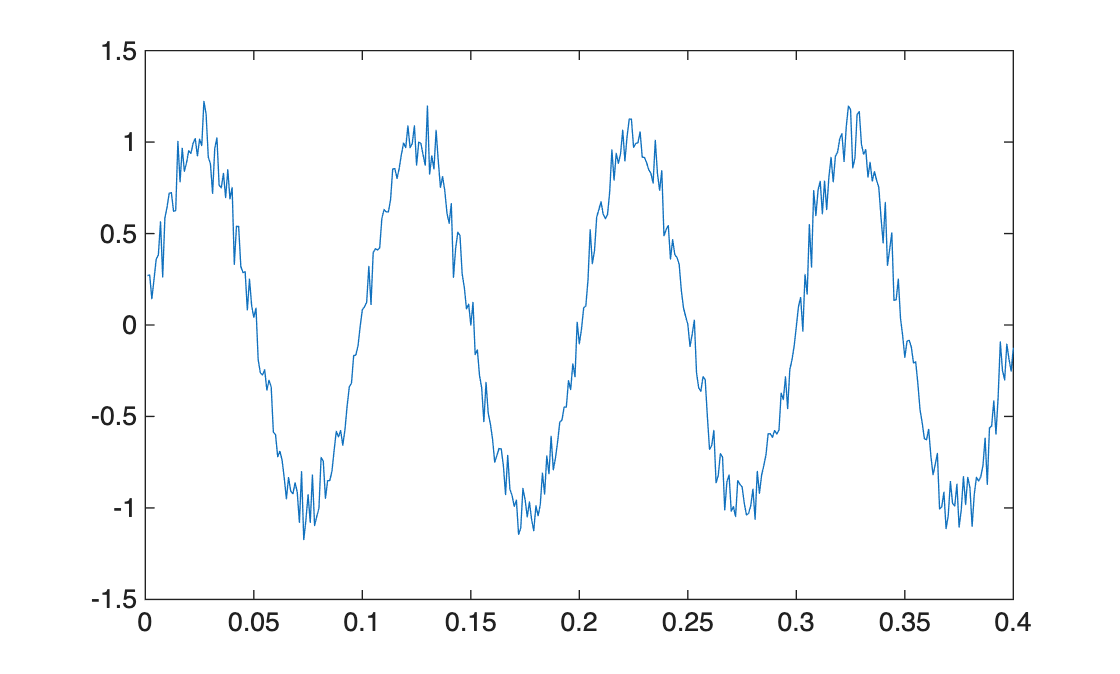

% add your code here
plot(t(1:400),x(1:400));

### 1.1.2.     Plot the linear line spectrum (N = 400)

Calculate the linear line spectrum of the sine signal in **Task 1.1.1. **and plot it with correct frequency axis. 

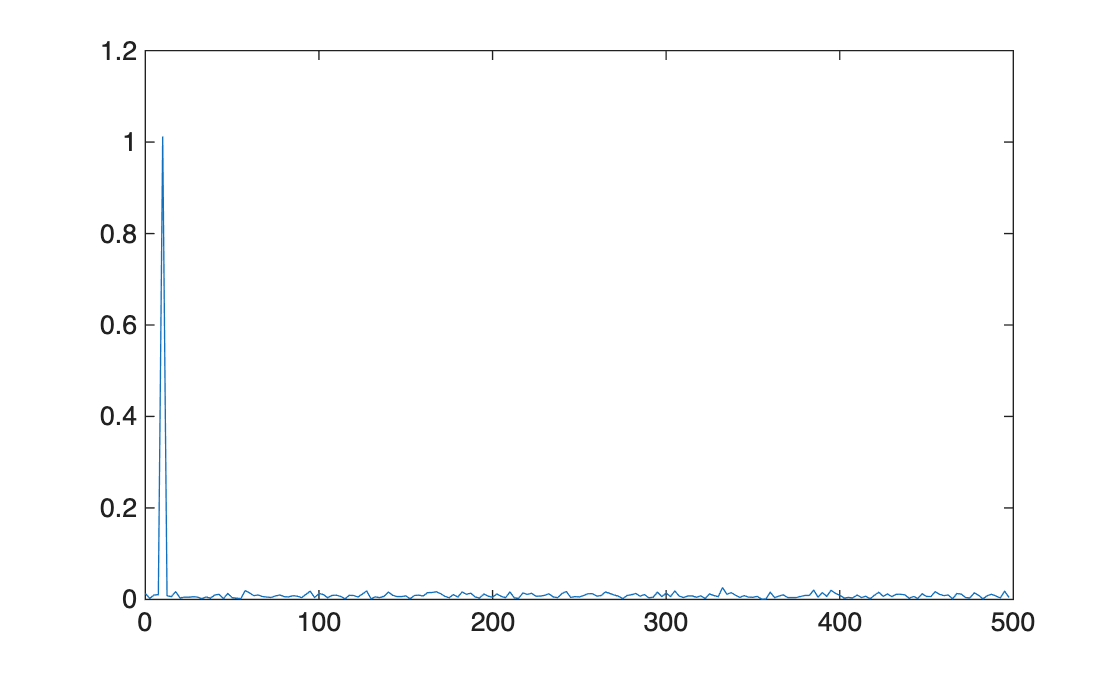

% add your code here
X=fft(x,400);
fs = 1e3;
plot( (0:400/2-1)*fs/400,2* abs(X(1:400/2))/400);

### 1.1.3.     Plot signal in time (N = 450)

Plot the first 450 samples of the signal versus time. Note this makes the signal non-periodic in the time window. 

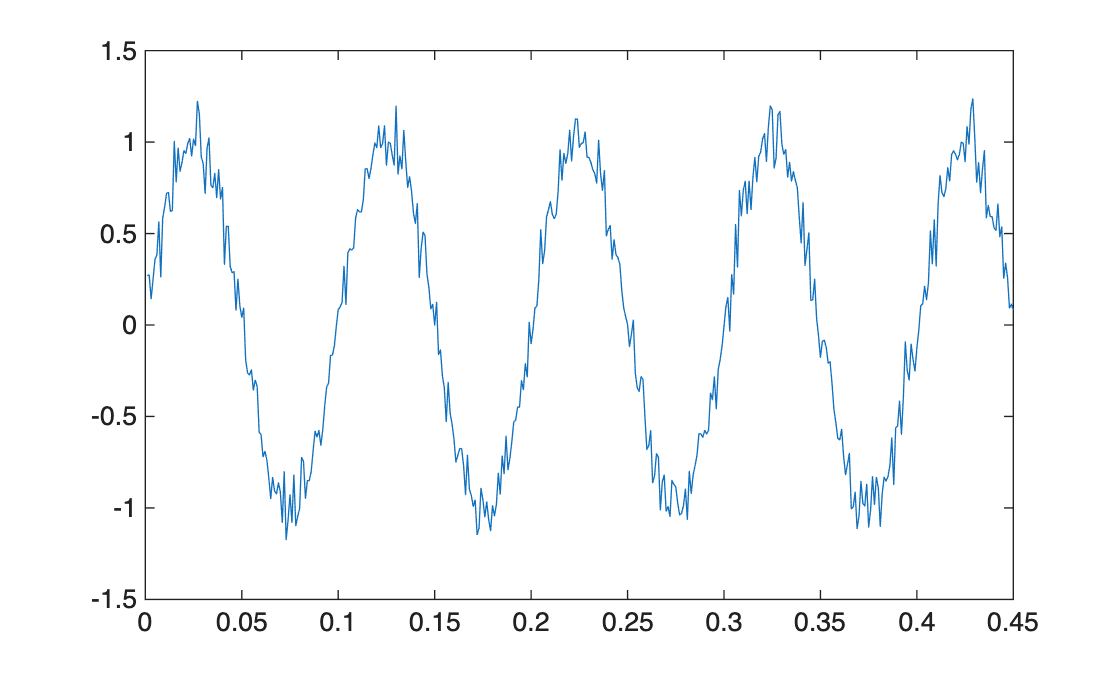

% add your code here
plot(t(1:450),x(1:450));

### 1.1.4.     Plot the linear line spectrum (N = 450)

Calculate the linear line spectrum of the sine signal in **Task 1.1.3. **and plot it with correct frequency axis. 

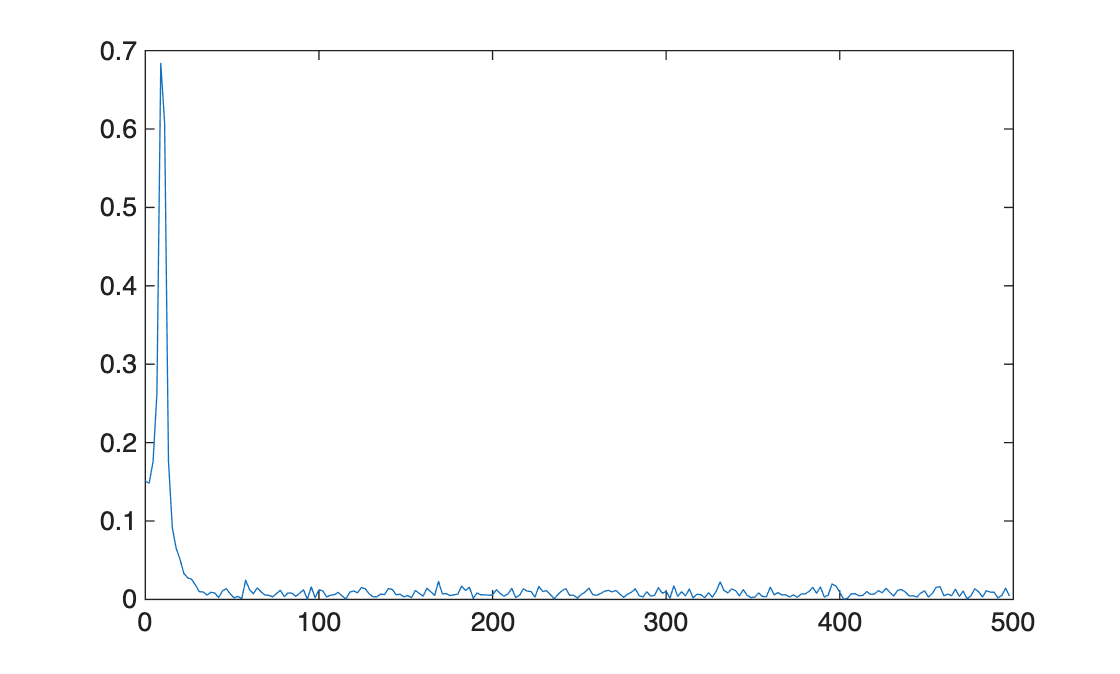

% add your code here
N2=450;
X2= fft(x,450);
plot((0:(450/2)-1)*fs/450,2*abs(X2(1:450/2))/450);

### 1.1.5.     Study the differences between the two spectra and conclude what has happened

***ANSWER: The N = 400 spectra gives a fair representation of the signal, with a peak at f = 10Hz as expected. ***

***The N = 450 spectra (non-periodic) gives two wrong frequencies equally spaced from the correct frequency f= 10Hz.***

## 1.2 Time windows

Create Hanning windows of length 400 and 450 using the commands:

and multiply these windows with the sine signals from **Task 1.1** (with 400 and 450 samples)

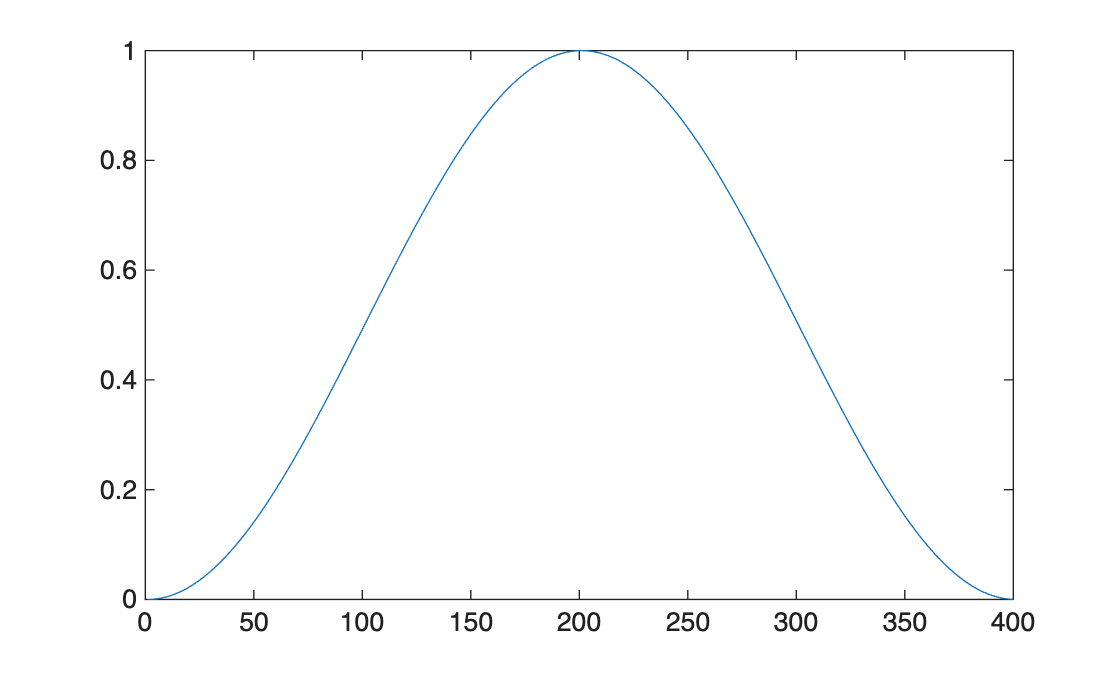

% add your code here
W1 = hanning(400,'periodic');
XW1 = fft(x(1:400) .* W1);
W2 = hanning(450,'periodic');
XW2 = fft(x(1:450) .* W2);

plot(1:400,W1) 

### 1.2.1.     Plot the linear line spectra of original and windowed signal (N = 400)

Plot the spectra with and without the Hanning window in the same figure.

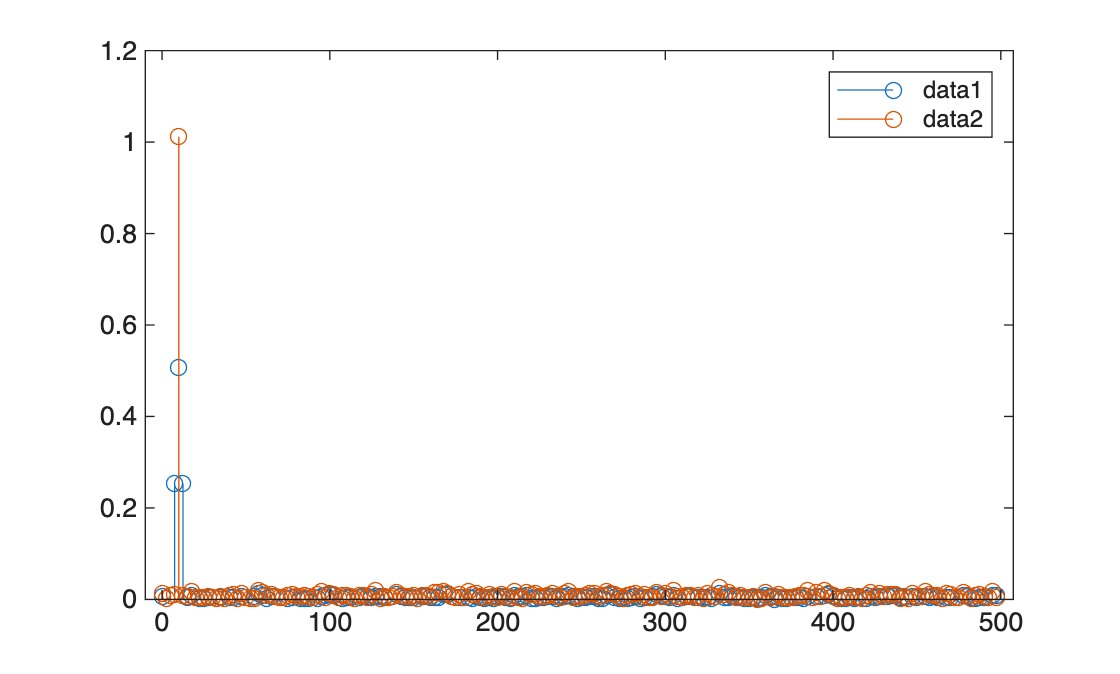

% add your code here
figure;
stem((0:(400/2)-1)*fs/400,2*abs(XW1(1:400/2))/400); hold on;
stem((0:(400/2)-1)*fs/400,2*abs(X(1:400/2))/400);
legend;
hold off;

### **1.2.2.     Study the differences between the two spectra and conclude what has happened**

***ANSWER: The spectra of the windowed function gives an f= 10Hz as well as two frequencies spaced equally apart from the real f.***

### 1.2.3.     Plot the linear line spectra of original and windowed signal (N = 450)

Plot the spectra with and without the Hanning window in the same figure.

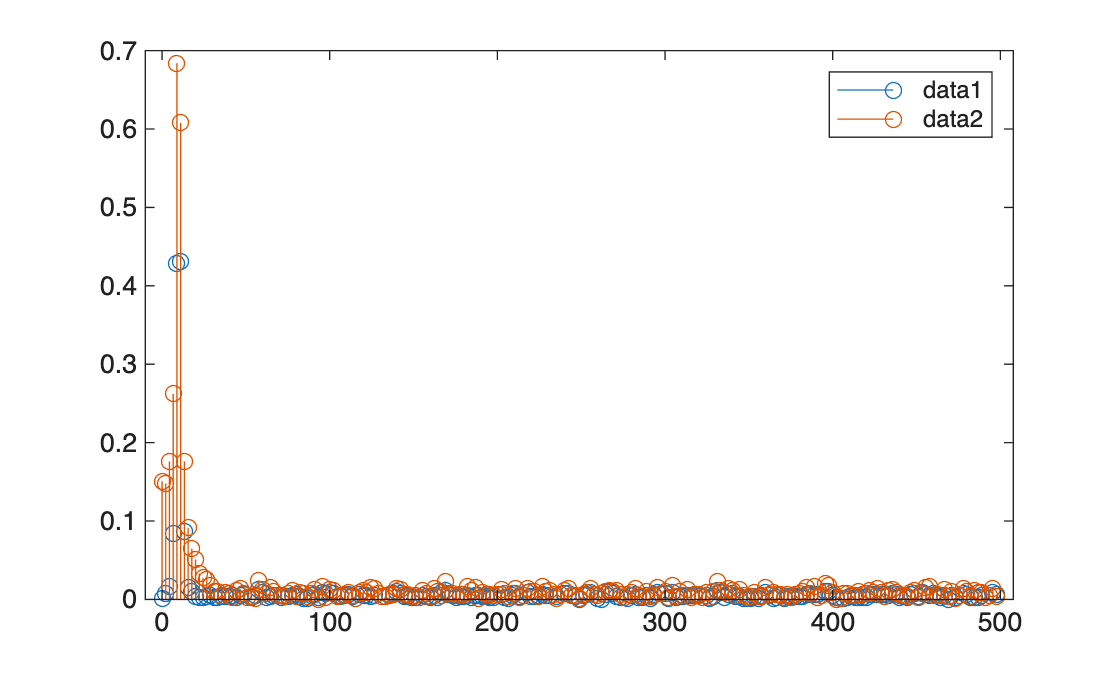

% add your code here
figure;
stem((0:(450/2)-1)*fs/450,2/450*abs(XW2(1:450/2))); hold on;
stem((0:(450/2)-1)*fs/450,2/450*abs(X2(1:450/2)));
legend;
hold off;

### 1.2.4.     Study the differences between the two spectra and conclude what has happened

***ANSWER: ***

## 1.3 Amplitude correction

Apply the so-called amplitude correction factor, see equations (9.7) and (9.8) in the course compendium, to the linear line spectra with Hanning windows from **Task 1.2**. The amplitude correction factor is for a Hanning window exactly equal to 0.5. 

% add your code here
C_a = mean(W1);
C_a2 = mean(W2);

rms_spectrum = sqrt(2) * abs(XW1)/C_a;
rms_spectrum2 = sqrt(2) * abs(XW2)/C_a2;

### 1.3.1.     Plot the linear line spectra of original and window-corrected signals (N = 400)

Plot the spectrum without the Hanning window in the same figure as the result with the Hanning window and amplitude correction.

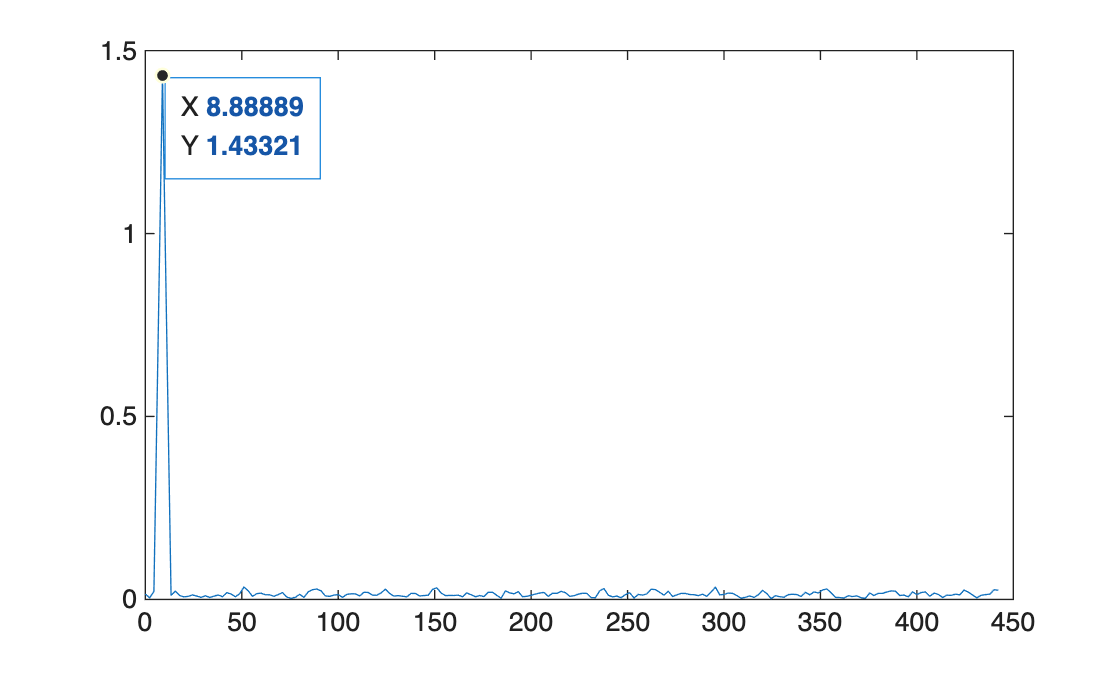

% add your code here
plot((0:(400/2)-1)*fs/400,2/400*rms_spectrum(1:200))

plot((0:(450/2)-1)*fs/450,2/450*rms_spectrum(1:225))

### 1.3.2.     Study the result, especially at or around 10 Hz, and conclude what has happened

***ANSWER: ****< Add your answer here >*

### 1.3.3.     Plot the linear line spectra of original and window-corrected signals (N = 450)

Plot the spectrum without the Hanning window in the same figure as the result with the Hanning window and amplitude correction.

% add your code here


### 1.3.4.     Study the result, especially at or around 10 Hz, and conclude what has happened

***ANSWER: ****< Add your answer here >*

# 2. WELCH METHOD

## 2.1. Power spectral density and cross-spectrum with MATLAB functions

**Background and Description of the measurement setup**

Aircraft engines are one of the loudest machines we commonly use. Acoustic liners in aircraft engines have been developed over the last decades, which have, in combination with higher pass-by-ratios, successfully decreased noise from aircraft engines. As part of a research project on such acoustic liners,measurements were made using two microphones (microphone 1 and 2) located in a so-called impedance tube, see; see the figure below. The distance between the two microphones was 34 mm, and the distance between the sample and the most nearby microphone was 169 mm. The project aimed to investigate the effect of excitation by high sound pressure levels on the acoustic properties of the perforate. There was only loudspeaker excitation up to 2000 Hz, but due to nonlinear effects at the perforate,there is signal content above this frequency.

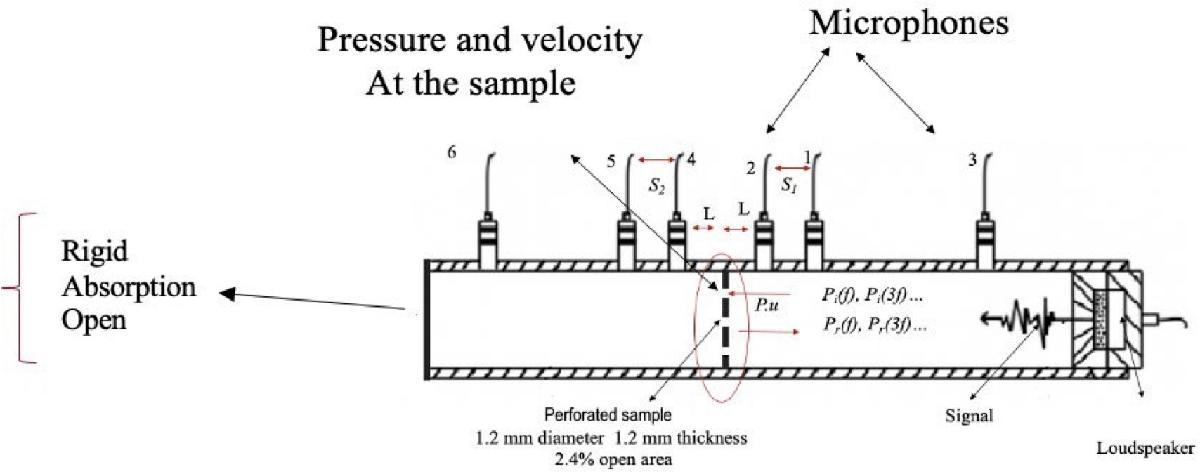

In this problem,you will use the data file `ImpTube12.mat``,` which can be downloaded from Canvas.The file contains two variables: `Mic12` which is a two-column matrix and `fs`, which gives the sampling frequency. To assess the two microphone signals, use the Welch method described in Chapter 9.4 in the course compendium. Make sure you have read this section before continuing. 

### 2.1.1.     Calculate and plot the power spectral densities using `pwelch` 

Begin by loading the `ImpTube12.mat` file. Use a Hanning `window WINDOW = hanning(NFFT, ‘periodic’)` and vary the number of averages by changing the block size `(NFFT = 1024 and 7680)`. The overlap should be set to 50% appropriate for random noise excitation. Plot the resulting spectra for the two microphone signals. 

% add your code here
load ImpTube12.mat;
NFFT = [1024,7680];
WINDOW1 = hanning(NFFT(1), 'periodic');
WINDOW2 = hanning(NFFT(2), 'periodic');


### 2.1.2.     Calculate and plot the cross spectra S12 and S21 using `CPSD`

Calculate the cross-spectra usign CPSD and the same analysis settings of **Task 2.1.1**. Plot the resulting power spectral densities against frequency with a logarithmic amplitude scale. 

Checkup question: When is a logarithmic scale preferred over a linear scale?

***ANSWER: ****< Add your answer here >*

% add your code here


### 2.1.3.     What is the effect of the averaging on the resulting power spectral densities?

***ANSWER: ****< Add your answer here >*

### 2.1.4.     How many averages do we get when we choose `NFFT = 1024` and `7680`?

***ANSWER: ****< Add your answer here >*

### 2.1.5.     Plot the amplitude and phase of the cross-power spectral densities

% add your code here


### 2.1.6.     Compare the amplitude and phase of S12 and S21 for NFFT = 1024

Are they different or identical? Explain why? 

***ANSWER: ****< Add your answer here >*

### 2.1.7.     Plot S12 in a logarithmic scale without taking the absolute value of S12

% add your code here


Explain why the plot looks the way it does. 

***ANSWER: ****< Add your answer here >*

## 2.2. Power spectral density using your own Matlab code

Calculate the power spectral densities directly using the Matlab `fft` command and compare your result to the results obtained in **Task 2.1.1.** for `NFFT = 1024` and 50% overlap. You will have to write a loop in Matlab to perform the averaging according to Welch’s technique. In this case, you should multiply the time signals with a Hanning window before performing the FFT. Use Parseval’s relation to make sure that you get the correct scaling.

### 2.2.1.     Plot your own and Matlab's PSDs and compare them

% add your code here


***ANSWER: ****< Add your answer here >*

### 2.2.2.     Replace the Hanning window with a rectangular window

Plot the PSD of the microphone signals using the Hanning and rectangular windows in the same plot. 

% add your code here


Compare the results and comment on what you see.

***ANSWER: ****< Add your answer here >*

# 3. SPECTRAL REPRESENTATIONS OF DIFFERENT SIGNAL TYPES

## 3.1.     Linear line spectra and block sizes

### 3.1.1.     Estimate the linear line spectrum of the sinusoid signal in Task 1.1

Use two different block sizes NFFT = 100 and 400 and plot the two spectra in the same figure.

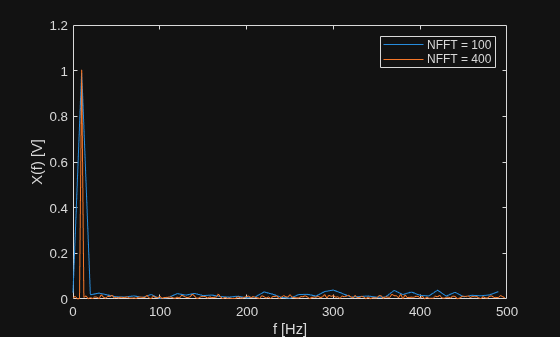

% add your code here
NFFT1 = 100;
NFFT4 = 400;

f = 10; % Frequency (Hz)
t = [1:64e3]'/1e3; % Time vector
x = sin(2*pi*f*t) + randn(size(t))/10;
X1 = fft(x,NFFT1);
X4 = fft(x,NFFT4);

fs = 1e3;
figure;
plot( (0:NFFT1/2-1)*fs/NFFT1,2* abs(X1(1:NFFT1/2))/NFFT1);
hold on
plot( (0:NFFT4/2-1)*fs/NFFT4,2* abs(X4(1:NFFT4/2))/NFFT4);
legend('NFFT = 100','NFFT = 400')
xlabel('f [Hz]')
ylabel('X(f) [V]')

### 3.1.2.     Estimate the linear line spectrum of the microphone signal in Task 2

Use two different block sizes NFFT = 1024 and 8192. Plot the two spectra in the same figure. 

% add your code here


### 3.1.3.     Conclude whether PSD is an appropriate representation for the signals in Task 3.1.1 and 3.1.2

***ANSWER: ****< Add your answer here >*

## 3.2.     Power spectral density and block sizes

### 3.2.1.     Estimate the PSD of the sinusoid signal in Task 1.1 using `PWELCH` 

Use two block sizes NFFT = 100 and 400 and plot in the same figure. 

% add your code here
NFFT1 = 100;
NFFT4 = 400;

f = 10; % Frequency (Hz)
t = [1:64e3]'/1e3; % Time vector
x = sin(2*pi*f*t) + randn(size(t))/10;




### 3.2.2.     Calculate the PSD of one of the microphone signals in Task 2 using `PWELCH` 

Use two block sizes NFFT = 1024 and 8192 and plot in the same figure.

% add your code here


### 3.2.3.     Conclude whether PSD is an appropriate representation for the signals in Task 3.2.1 and 3.2.2

***ANSWER: ****< Add your answer here >*